# Image Denoising with Vector Operator Sparsity Regularisation

*Eva-Maria Brinkmann, Martin Burger, Joana Sarah Grah*

"Unified Models for Second-Order TV-Type Regularisation in Imaging - A new Perspective Based on Vector Operators." *Journal of Mathematical Imaging and Vision*. 2018.

This code performs denoising for a given image by using the unified VOS model optimised by a primal-dual algorithm.

## Load Trui test image and add Gaussian noise

load Trui.mat
[m,n] = size(img);

noiseMean = 0;
noiseVariance = 0.05;
imgNoisy = imnoise(img,'gaussian',noiseMean,noiseVariance);

## Set Parameters

alpha = 1/4.5;                                 %global regularisation weighting parameter
beta1 = 0;                                     %weighting parameter curl
beta2 = 1/8;                                   %weighting parameter divergence
beta3 = 1;                                     %weighting parameter shear1
beta4 = 1/2;                                   %weighting parameter shear2

Dy = spdiags([-ones(m,1) ones(m,1)], [0 1], m, m);
Dy(m,:) = 0;
Dx = spdiags([-ones(n,1) ones(n,1)], [0 1], n, n);
Dx(n,:) = 0;
DX = kron(Dx, speye(m));                       %gradient matrices
DY = kron(speye(n), Dy);
I = speye(m*n);                                %operator K
Z = sparse(m*n,m*n);
K = [DX -I Z; DY Z -I; Z -beta1*DY beta1*DX; Z -beta2*DX' -beta2*DY'; Z beta3*DX' -beta3*DY'; Z beta4*DY beta4*DX];

algorithmParam.sigma = 1/sqrt(normest(K'*K));  %primal step size

algorithmParam.tau = algorithmParam.sigma;     %dual step size
algorithmParam.theta = 1;                      %primal-dual overrelaxation parameter
algorithmParam.maxIter = 15000;                %maximum number of primal-dual iterations
algorithmParam.epsilon = 1e-3;                 %primal-dual residual threshold

## Optimisation

[u, w] = primaldualOptimisation_live(imgNoisy, K, algorithmParam, alpha);

Iteration 250. Primal-Dual Residual: 0.00061408. Primal-Dual Gap: 0.056217
Iteration 500. Primal-Dual Residual: 0.00033814. Primal-Dual Gap: 0.031297
Iteration 750. Primal-Dual Residual: 0.0002354. Primal-Dual Gap: 0.021736
Iteration 1000. Primal-Dual Residual: 0.00018111. Primal-Dual Gap: 0.016623
Iteration 1250. Primal-Dual Residual: 0.00014686. Primal-Dual Gap: 0.013411
Iteration 1500. Primal-Dual Residual: 0.00012307. Primal-Dual Gap: 0.011187
Iteration 1750. Primal-Dual Residual: 0.00010552. Primal-Dual Gap: 0.0095729
Iteration 2000. Primal-Dual Residual: 9.164e-05. Primal-Dual Gap: 0.0083421
Iteration 2250. Primal-Dual Residual: 8.0988e-05. Primal-Dual Gap: 0.0073926
Iteration 2500. Primal-Dual Residual: 7.2939e-05. Primal-Dual Gap: 0.0066264
Iteration 2750. Primal-Dual Residual: 6.6249e-05. Primal-Dual Gap: 0.0060056
Iteration 3000. Primal-Dual Residual: 6.0812e-05. Primal-Dual Gap: 0.0054885
Iteration 3250. Primal-Dual Residual: 5.5902e-05. Primal-Dual Gap: 0.005048
Iteration 3


disp(['Relative Error: ',num2str(norm(img-u)/norm(img)),', PSNR: ',num2str(psnr(u,img)),', SSIM:',num2str(ssim(u,img))]);

Relative Error: 0.027311, PSNR: 26.567, SSIM:0.81082


## Visualisation

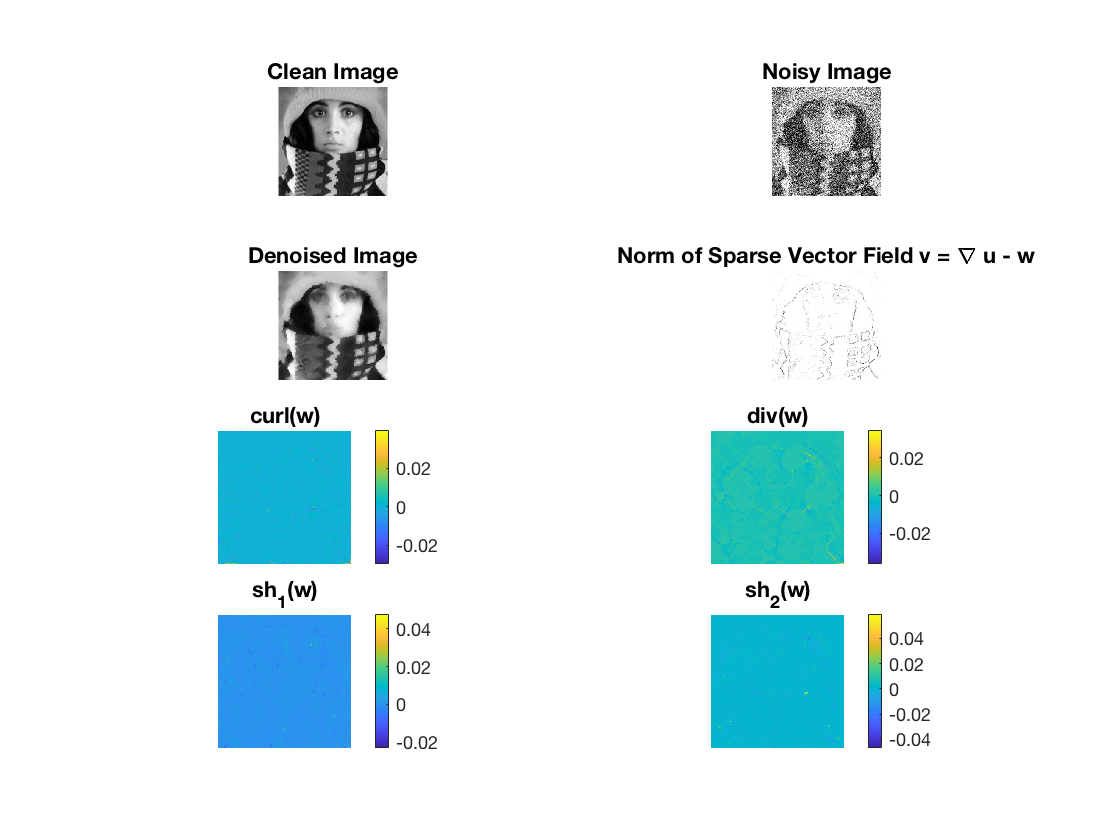

w1 = w(:,:,1);
w2 = w(:,:,2);
norm_v = sqrt((reshape(DX*u(:),[m,n]) - w1).^2 + (reshape(DY*u(:),[m,n]) - w2).^2);
curl_w = reshape(DY'*w1(:) - DX'*w2(:),[m,n]);
div_w = reshape(-DX'*w1(:) -DY'*w2(:),[m,n]);
sh1_w = reshape(DY*w2(:) - DX*w1(:),[m,n]);
sh2_w = reshape(DY*w1(:) + DX*w2(:),[m,n]);

cmap = colormap('gray');
figure;
subplot(421);imagesc(img);title('Clean Image');axis off;axis image;colormap(gca,'gray');
subplot(422);imagesc(imgNoisy);title('Noisy Image');axis off;axis image;colormap(gca,'gray');
subplot(423);imagesc(u);title('Denoised Image');axis off;axis image;colormap(gca,'gray');
subplot(424);imagesc(norm_v);title('Norm of Sparse Vector Field v = \nabla u - w');axis off;axis image;colormap(gca,flipud(cmap));
subplot(425);imagesc(curl_w);title('curl(w)');colorbar;axis off;axis image;colormap(gca,'parula');
subplot(426);imagesc(div_w);title('div(w)');colorbar;axis off;axis image;colormap(gca,'parula');
subplot(427);imagesc(sh1_w);title('sh_1(w)');colorbar;axis off;axis image;colormap(gca,'parula');
subplot(428);imagesc(sh2_w);title('sh_2(w)');colorbar;axis off;axis image;colormap(gca,'parula');